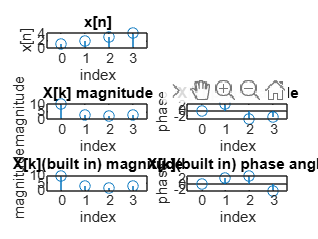

x=input("Enter x[n]:");
N=length(x);
X=zeros(1,N);
for k=0:N-1
    for n=0:N-1
        X(k+1)=X(k+1)+x(n+1)*exp((-2j*pi*n*k)/N);
    end
end
X_fft = fft(x);
subplot(321)
stem(0:N-1,x);
xlabel("index");
ylabel("x[n]");
title("x[n]");
subplot(323)
stem(0:N-1,abs(X));
xlabel("index");
ylabel("magnitude");
title("X[k] magnitude");
subplot(324)
stem(0:N-1,angle(X));
xlabel("index");
ylabel("phase");
title("X[k] phase angle");
subplot(325)
stem(0:N-1,abs(X_fft));
xlabel("index");
ylabel("magnitude");
title("X[k](built in) magnitude");
subplot(326)
stem(0:N-1,angle(X_fft));
xlabel("index");
ylabel("phase");
title("X[k](built in) phase angle");